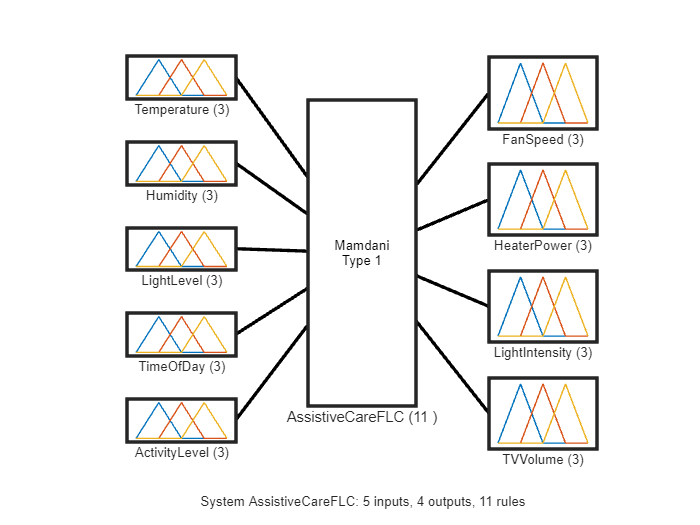

% Create a new FIS
fis = mamfis('Name', 'AssistiveCareFLC');

% Define input variables with sufficient range and overlap
% Temperature
fis = addInput(fis, [0 40], 'Name', 'Temperature');
fis = addMF(fis, 'Temperature', 'trimf', [0 10 20], 'Name', 'Cold');
fis = addMF(fis, 'Temperature', 'trimf', [10 20 30], 'Name', 'Comfortable');
fis = addMF(fis, 'Temperature', 'trimf', [20 30 40], 'Name', 'Hot');

% Humidity
fis = addInput(fis, [0 100], 'Name', 'Humidity');
fis = addMF(fis, 'Humidity', 'trimf', [0 25 50], 'Name', 'Low');
fis = addMF(fis, 'Humidity', 'trimf', [25 50 75], 'Name', 'Medium');
fis = addMF(fis, 'Humidity', 'trimf', [50 75 100], 'Name', 'High');

% Light Level
fis = addInput(fis, [0 100], 'Name', 'LightLevel');
fis = addMF(fis, 'LightLevel', 'trimf', [0 25 50], 'Name', 'Dark');
fis = addMF(fis, 'LightLevel', 'trimf', [25 50 75], 'Name', 'Moderate');
fis = addMF(fis, 'LightLevel', 'trimf', [50 75 100], 'Name', 'Bright');

% Time of Day
fis = addInput(fis, [0 24], 'Name', 'TimeOfDay');
fis = addMF(fis, 'TimeOfDay', 'trimf', [0 6 12], 'Name', 'Morning');
fis = addMF(fis, 'TimeOfDay', 'trimf', [6 12 18], 'Name', 'Afternoon');
fis = addMF(fis, 'TimeOfDay', 'trimf', [12 18 24], 'Name', 'Night');

% User Activity Level
fis = addInput(fis, [0 100], 'Name', 'ActivityLevel');
fis = addMF(fis, 'ActivityLevel', 'trimf', [0 25 50], 'Name', 'Low');
fis = addMF(fis, 'ActivityLevel', 'trimf', [25 50 75], 'Name', 'Medium');
fis = addMF(fis, 'ActivityLevel', 'trimf', [50 75 100], 'Name', 'High');

% Define output variables
% Fan Speed
fis = addOutput(fis, [0 100], 'Name', 'FanSpeed');
fis = addMF(fis, 'FanSpeed', 'trimf', [0 25 50], 'Name', 'Low');
fis = addMF(fis, 'FanSpeed', 'trimf', [25 50 75], 'Name', 'Medium');
fis = addMF(fis, 'FanSpeed', 'trimf', [50 75 100], 'Name', 'High');

% Heater Power
fis = addOutput(fis, [0 100], 'Name', 'HeaterPower');
fis = addMF(fis, 'HeaterPower', 'trimf', [0 25 50], 'Name', 'Low');
fis = addMF(fis, 'HeaterPower', 'trimf', [25 50 75], 'Name', 'Medium');
fis = addMF(fis, 'HeaterPower', 'trimf', [50 75 100], 'Name', 'High');

% Light Intensity
fis = addOutput(fis, [0 100], 'Name', 'LightIntensity');
fis = addMF(fis, 'LightIntensity', 'trimf', [0 25 50], 'Name', 'Low');
fis = addMF(fis, 'LightIntensity', 'trimf', [25 50 75], 'Name', 'Medium');
fis = addMF(fis, 'LightIntensity', 'trimf', [50 75 100], 'Name', 'High');

% TV Volume
fis = addOutput(fis, [0 100], 'Name', 'TVVolume');
fis = addMF(fis, 'TVVolume', 'trimf', [0 25 50], 'Name', 'Low');
fis = addMF(fis, 'TVVolume', 'trimf', [25 50 75], 'Name', 'Medium');
fis = addMF(fis, 'TVVolume', 'trimf', [50 75 100], 'Name', 'High');

% Define rules
rules = [
    "Temperature==Cold & Humidity==Low => FanSpeed=Low, HeaterPower=High, LightIntensity=Low, TVVolume=Low"
    "Temperature==Cold & Humidity==Medium => FanSpeed=Low, HeaterPower=High, LightIntensity=Medium, TVVolume=Medium"
    "Temperature==Comfortable & Humidity==Medium => FanSpeed=Low, HeaterPower=Low, LightIntensity=High, TVVolume=High"
    "Temperature==Hot & Humidity==High => FanSpeed=High, HeaterPower=Low, LightIntensity=Low, TVVolume=Low"
    "Temperature==Hot & Humidity==Low => FanSpeed=Medium, HeaterPower=Low, LightIntensity=High, TVVolume=Medium"
    "Temperature==Comfortable & Humidity==High => FanSpeed=Medium, HeaterPower=Low, LightIntensity=Medium, TVVolume=Medium"
    "Temperature==Cold & LightLevel==Dark => FanSpeed=Low, HeaterPower=High, LightIntensity=Medium, TVVolume=Medium"
    "Temperature==Hot & LightLevel==Bright => FanSpeed=High, HeaterPower=Low, LightIntensity=High, TVVolume=Low"
    "TimeOfDay==Night & ActivityLevel==Low => FanSpeed=Low, HeaterPower=Low, LightIntensity=Low, TVVolume=Low"
    "TimeOfDay==Morning & ActivityLevel==High => FanSpeed=Medium, HeaterPower=High, LightIntensity=High, TVVolume=Medium"
    "TimeOfDay==Afternoon & ActivityLevel==Medium => FanSpeed=Medium, HeaterPower=Low, LightIntensity=High, TVVolume=Medium"
];

% Add rules to the FIS
fis = addRule(fis, rules);

% Display FIS structure
figure;
plotfis(fis);

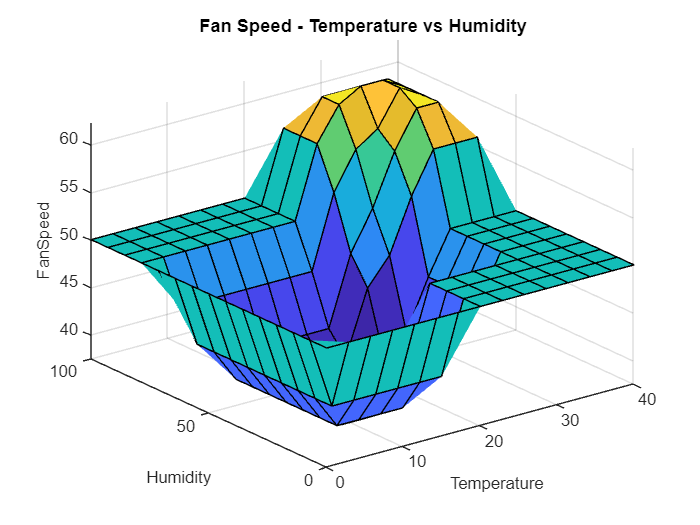


% View the control surface plot for Fan Speed output
figure;
gensurf(fis, [1 2], 1);
title('Fan Speed - Temperature vs Humidity');

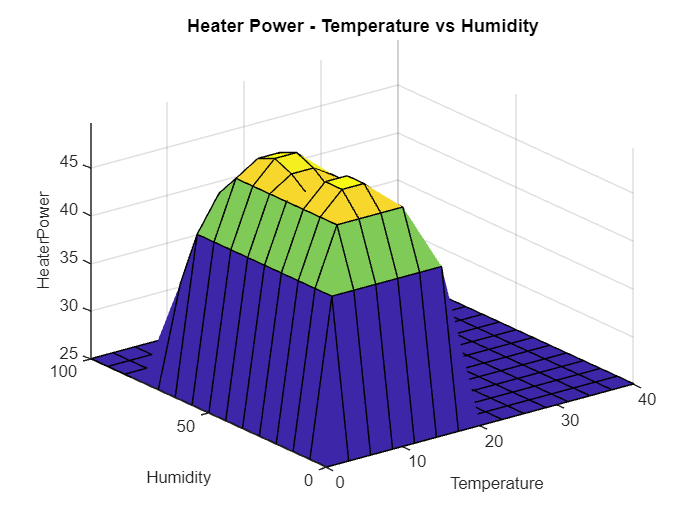


% View the control surface plot for Heater Power output
figure;
gensurf(fis, [1 2], 2);
title('Heater Power - Temperature vs Humidity');

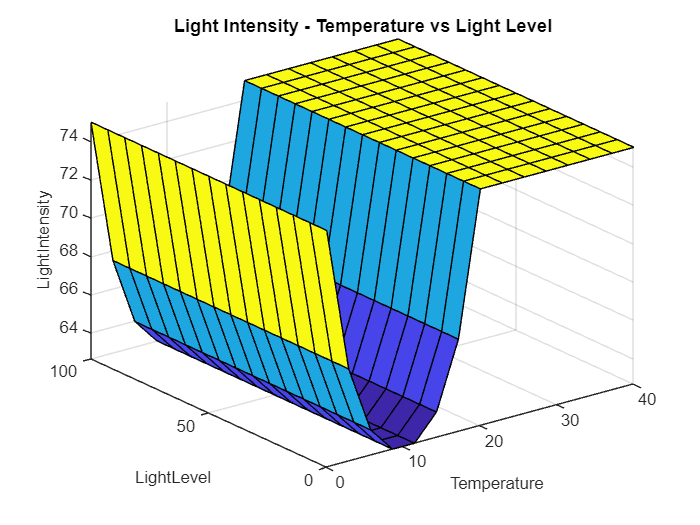


% View the control surface plot for Light Intensity output
figure;
gensurf(fis, [1 3], 3);
title('Light Intensity - Temperature vs Light Level');

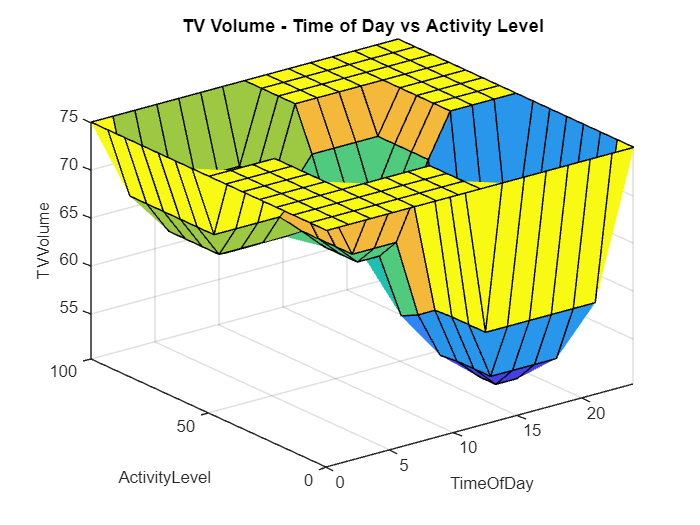


% View the control surface plot for TV Volume output
figure;
gensurf(fis, [4 5], 4);
title('TV Volume - Time of Day vs Activity Level');


% Test FIS with an example input
input = [20 50 40 14 50]; % Example input: [Temp, Humidity, Light Level, Time of Day, Activity Level]
output = evalfis(fis, input);
disp(['Fan Speed: ', num2str(output(1))]);

Fan Speed: 36.6499


disp(['Heater Power: ', num2str(output(2))]);

Heater Power: 25


disp(['Light Intensity: ', num2str(output(3))]);

Light Intensity: 75


disp(['TV Volume: ', num2str(output(4))]);

TV Volume: 63.3501



% To view the rules, use the Fuzzy Logic Designer app:
fuzzyLogicDesigner(fis);